fname = 'netlist.cir';
scam;

Full documentation available at www.swarthmore.edu/NatSci/echeeve1/Ref/mna/MNA1.html


Started -- please be patient.

Done! Elapsed time = 3.30781 seconds.

Netlist
     V1 0 1 1
     L1 1 2 0.1
     C 2 0 0.1
     I1 2 0 1
     R 2 3 4
     C 3 0 0.1
     I2 3 0 1
     L2 3 4 0.1
     V2 0 4 1
 
Solved variables:


$$\left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ v_{4}\\ I_{\mathrm{V1}}\\ I_{\mathrm{V2}} \end{array}\right)$$


Full documentation available at www.swarthmore.edu/NatSci/echeeve1/Ref/mna/MNA1.html


L1 = sym('L1');
L2 = sym('L2');
L = sym('L');
V1 = sym('V1');
V2 = sym('V2');
I1 = sym('I1');
I2 = sym('I2');
D1 = sym('D1');
D2 = sym('D2');
d = sym('d');
H = v_2-v_3;
H = subs(H, L1, L/D1^2);
H = subs(H, L2, L/D2^2);
H = subs(H, V1, V1/D1*d);
H = subs(H, V2, V2/D2*d);
H = subs(H, I1, I1*d);
H = subs(H, I2, I2*d);
H=H/d;
H=simplifyFraction(H);
H=collect(H)

$$H = \frac{\left(C\,I_{2}\,L^{2}\,R-C\,I_{1}\,L^{2}\,R\right)\,s^{3}+\left(C\,D_{2}\,L\,R\,V_{2}-C\,D_{1}\,L\,R\,V_{1}\right)\,s^{2}+\left({D_{1}}^{2}\,I_{2}\,L\,R-{D_{2}}^{2}\,I_{1}\,L\,R\right)\,s+{D_{1}}^{2}\,D_{2}\,R\,V_{2}-D_{1}\,{D_{2}}^{2}\,R\,V_{1}}{\left(C^{2}\,L^{2}\,R\right)\,s^{4}+\left(2\,C\,L^{2}\right)\,s^{3}+\left(C\,L\,R\,{D_{1}}^{2}+C\,L\,R\,{D_{2}}^{2}\right)\,s^{2}+\left(L\,{D_{1}}^{2}+L\,{D_{2}}^{2}\right)\,s+{D_{1}}^{2}\,{D_{2}}^{2}\,R}$$

%lt = latex(H);

syms C R R2 Vg
[Hn, Hd] = numden(H);

I1n = (V1-V2)/(D1*R);
I2n = (V2-V1)/(D2*R);

D1n = 0.8;
D2n = 0.2;

Hn = subs(Hn, [I1, I2], [I1n, I2n]);
Hn = subs(Hn, [V1, V2], [1/D1, 1/D2]);
Hn = subs(Hn, [C, L, R, R2, D1, D2],...
    [1e-6, 1e-6, 4, 1000, D1n, D2n])

$$Hn = \frac{3\,s^{3}}{128000000000000000}+\frac{39\,s}{3200000}+\frac{12}{5}$$


Hd = subs(Hd, [I1, I2], [I1n, I2n]);
Hd = subs(Hd, [V1, V2], [1/D1, 1/D2]);
Hd = subs(Hd, [C, L, R, R2 D1, D2],...
    [1e-6, 1e-6, 4, 1000, D1n, D2n])

$$Hd = \frac{s^{4}}{250000000000000000000000}+\frac{s^{3}}{500000000000000000}+\frac{17\,s^{2}}{6250000000000}+\frac{17\,s}{25000000}+\frac{64}{625}$$


nc = sym2poly(Hn)

nc =     0.0000         0    0.0000    2.4000


dc = sym2poly(Hd)

dc =     0.0000    0.0000    0.0000    0.0000    0.1024


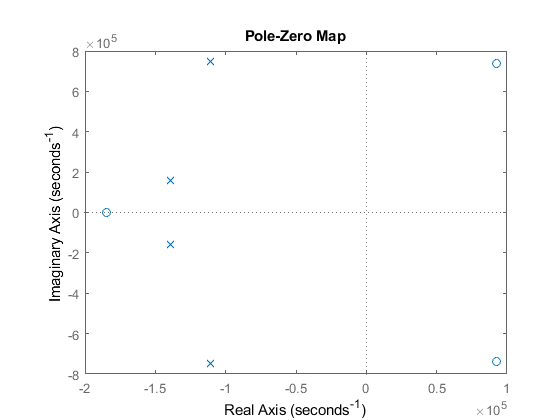


Htf = tf(nc, dc);
pzmap(Htf);

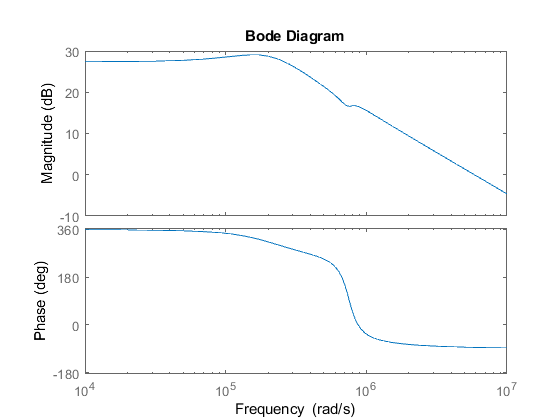

bode(Htf)